**AVD Group 01**

Hanchen Li

Please see **report** for theory and explaination, be aware of the **units** in angle

% House Keeping
clear
clc
close all

g = 9.80665;      % Standard acceleration of gravity (m/s^2)

Before everything

x_w_l = 25;      % Distance between nosetip to leading edge (m)

Input parameter form Weight and Balance Estimation code

**with empty trim tank**

% aftmost CG location (m)
x_CG_aft = 36.5021;
z_CG_aft = -0.4290;
W_CG_aft = 2.1828e5;

x_CG_aft_down = 36.4759;
z_CG_aft_down = -1.1441;
W_CG_aft_down = 2.1828e5;

% foremost CG location (m)
x_CG_for = 35.6418;
z_CG_for = -0.0460;
W_CG_for = 3.9818e5;

x_CG_for_down = 35.7796;
z_CG_for_down = -0.3505;
W_CG_for_down = 4.1700e5;

## **1. Neutral Point**

**Find fuselage coefficient of pitching moment**


x_c_4 = x_w_l + 14.9785211301574 * 0.25; % Wing-root 1/4 chord position (m) % Undefined

L_f = 75.5;                              % Total fuselage length (m)

% Find K_f via NACA TR 177

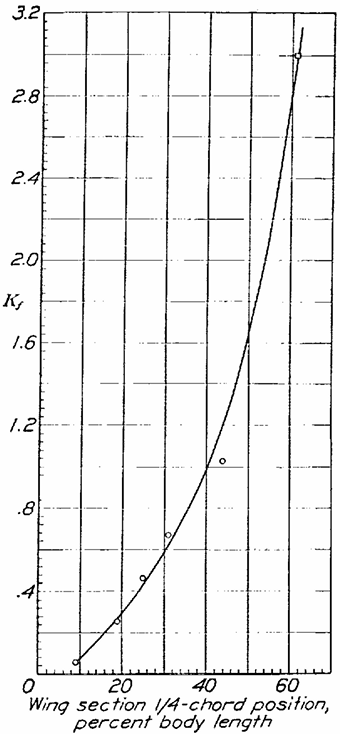


x_c_4 / L_f

ans = 0.3807


K_f = 0.6 + 4 * (x_c_4 / L_f - 0.3)

K_f = 0.9229


w_f = 6.88;          % Fuselage maximum width (m)

c = 9.9496;          % Mean chord length (m) % Undefined

S_w = 548.70;        % Reference wing area (m^2)

d_CM_f = K_f * (L_f * (w_f ^ 2)) / (c * S_w) % (1/rad)

d_CM_f = 0.6041

**Find wing's zero lift pitching moment**

AR = 7.70;              % Aspect Ratio

Sweep = 22.6407;        % Wing quarter chord sweep (degree)
Sweep = deg2rad(Sweep); % Wing quarter chord sweep (rad)

twist = 4.9956;         % Wing twist (degree)

i_w = -0.4888;          % Wing setting angle (degree)
i_w = deg2rad(i_w);     % Wing setting angle (rad)

C_m_airf_0 = -0.13;     % Incompressible airfoil zero lift pitching moment

d_CL_w_0 = 3.9474;      % Incompressible wing lift curve slope (1/rad) % Undefined

% Wing's zero lift pitching moment 'coefficient'
k_C_m0_w = (C_m_airf_0 * (AR * (cos(Sweep) ^ 2)) / (AR + 2 * cos(Sweep)) - 0.01 * twist) / d_CL_w_0

k_C_m0_w = -0.0353

**Other input parameters**

n_h = 0.9;                % Tail efficiency factor

B_w = 64.99;              % Wing span (m)

Taper = 0.2348;           % Wing taper ratio

V_S = 62.65;              % Landing stall speed (m/s)

x_ac_w_0 = x_w_l + 10.10; % Wing aerodynamic center at M=0 (m)

x_ac_h_0 = 72.2;          % Horizontal tailplane aerodynamic center at M=0 (m)

h_h = 5.3;                % Vertical distance between wing and horizontal tailplane chord (m)

l_h = x_ac_h_0 - x_ac_w_0 % (m)

l_h = 37.1000


S_h = 110.3938;           % Horizontal tailplane area (m^2)

K = 0.068373;

K_tail = 0.072002;

Notice $Z_t$ is $+\textrm{ve}$ if thrustline under CG

Z_t = -1.1715;            % Thrustline above datum (m)

**Find compressible effect on aerodynamic center**

x_ac_M

% x_ac = x_ac_M(x_ac_0, M, S_wing)

**Find downwash derivative**

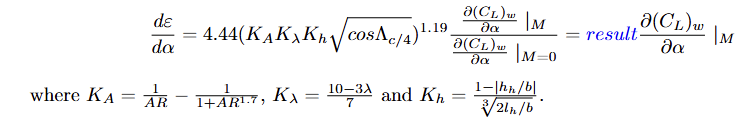

K_A = 1 / AR - 1 / (1 + AR ^ 1.7);

K_Taper = (10 - 3 * Taper) / 7;

K_h = (1 - abs(h_h / B_w)) / ((2 * l_h / B_w) ^ (1 / 3));

% Downwash derivative 'coefficient'
k_d_downwash = (4.44 * (K_A * K_Taper * K_h * (cos(Sweep)) ^ 0.5) ^ 1.19) / d_CL_w_0

k_d_downwash = 0.0829

results


$$x_{\textrm{np}} =\frac{\frac{{d\left(C_L \right)}_W }{d\alpha }{\left(x_{\textrm{ac}} \right)}_w -\frac{{\delta \left(C_M \right)}_f }{\delta \alpha }\bar{c} +\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }{\left(x_{\textrm{ac}} \right)}_h }{\frac{{d\left(C_L \right)}_W }{d\alpha }+\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }}$$


**0-1** Takeoff **&** **4-5** Missed approach (Takeoff)

[T_TO, c_TO, P_TO, rho_TO] = atmosisa(0);

V_TO = 1.2 * V_S    % Takeoff velocity (m/s)

V_TO = 75.1800


a_0_w_TO = -0.13356; % Wing takeoff zero lift angle of attack (rad)
d_CL_w_TO = 4.2191;  % Wing takeoff lift curve slope (1/rad)

a_0_h_TO = 0;        % Horizontal tailplane takeoff zero lift angle of attack (rad)
d_CL_h_TO = 3.5827;  % Horizontal tailplane takeoff lift curve slope (1/rad)

CD_0_TO = 0.049258;  % Takeoff drag coefficient

% No compressibility effect 
x_ac_w_TO = x_ac_w_0

x_ac_w_TO = 35.1000

x_ac_h_TO = x_ac_h_0

x_ac_h_TO = 72.2000


d_downwash_TO = k_d_downwash * d_CL_w_0

d_downwash_TO = 0.3272


C_m0_w_TO = k_C_m0_w * d_CL_w_0

C_m0_w_TO = -0.1393


% Find neutral point
x_np_TO = (d_CL_w_TO * x_ac_w_TO - d_CM_f * c + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w) * x_ac_h_TO) / ...
    ((d_CL_w_TO + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w)))

x_np_TO = 37.2868

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

[T_c1, c_c1, P_c1, rho_c1] = atmosisa(convlength(28000, 'ft','m'));

V_c1 = 0.83 * c_c1   % 1st cruise velocity (m/s)

V_c1 = 253.8045


a_0_w_c1 = -0.08465; % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_c1 = 4.4359;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_c1 = 0;        % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_c1 = 3.925;   % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_0_c1 = 0.018794;    % 1st cruise drag coefficient

% Compressibility effect 
M_c1 = 0.83;

x_ac_w_c1 = x_ac_M(x_ac_w_0, M_c1, S_w)

x_ac_w_c1 = 35.8384

x_ac_h_c1 = x_ac_M(x_ac_h_0, M_c1, S_h)

x_ac_h_c1 = 72.5312


d_downwash_c1 = k_d_downwash * d_CL_w_c1

d_downwash_c1 = 0.3677


C_m0_w_c1 = k_C_m0_w * d_CL_w_c1

C_m0_w_c1 = -0.1565


% Find neutral point
x_np_c1 = (d_CL_w_c1 * x_ac_w_c1 - d_CM_f * c + n_h * d_CL_h_c1 * (1 - d_downwash_c1) * (S_h / S_w) * x_ac_h_c1) / ...
    ((d_CL_w_c1 + n_h * d_CL_h_c1 * (1 - d_downwash_c1) * (S_h / S_w)))

x_np_c1 = 37.9831

**3-4** Descent to land **&** **7-8** Descent to land

[T_L, c_L, P_L, rho_L] = atmosisa(0);

V_L = 1.3 * V_S    % Takeoff velocity (m/s)

V_L = 81.4450


a_0_w_L = -0.13356; % Wing landing zero lift angle of attack (rad)
d_CL_w_L = 4.7729;  % Wing landing lift curve slope (1/rad)

a_0_h_L = 0;        % Horizontal tailplane landing zero lift angle of attack (rad)
d_CL_h_L = 3.5887;  % Horizontal tailplane landing lift curve slope (1/rad)

CD_0_L = 0.09319;   % landing drag coefficient

% No compressibility effect 
x_ac_w_L = x_ac_w_0

x_ac_w_L = 35.1000

x_ac_h_L = x_ac_h_0

x_ac_h_L = 72.2000


d_downwash_L = k_d_downwash * d_CL_w_0

d_downwash_L = 0.3272


C_m0_w_L = k_C_m0_w * d_CL_w_0

C_m0_w_L = -0.1393


% Find neutral point
x_np_L = (d_CL_w_L * x_ac_w_L - d_CM_f * c + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w) * x_ac_h_L) / ...
    ((d_CL_w_L + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w)))

x_np_L = 37.0593

**5-6** Cruise to alternate destination 370 km away

[T_c2, c_c2, P_c2, rho_c2] = atmosisa(convlength(18000, 'ft','m'));

V_c2 = convvel(400, 'kts', 'm/s')  % 2nd cruise velocity (m/s)

V_c2 = 205.7778


a_0_w_c2 = -0.08465; % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_c2 = 4.2537;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_c2 = 0;        % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_c2 = 3.8219;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_0_c2 = 0.018718;  % 2nd cruise drag coefficient

% Compressibility effect 
M_c2 = 0.6460;

x_ac_w_c2 = x_ac_M(x_ac_w_0, M_c2, S_w)

x_ac_w_c2 = 35.2828

x_ac_h_c2 = x_ac_M(x_ac_h_0, M_c2, S_h)

x_ac_h_c2 = 72.2820


d_downwash_c2 = k_d_downwash * d_CL_w_c2

d_downwash_c2 = 0.3526


C_m0_w_c2 = k_C_m0_w * d_CL_w_c2

C_m0_w_c2 = -0.1501


% Find neutral point
x_np_c2 = (d_CL_w_c2 * x_ac_w_c2 - d_CM_f * c + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w) * x_ac_h_c2) / ...
    ((d_CL_w_c2 + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w)))

x_np_c2 = 37.5298

**6-7** Loiter at 5000 ft for 45 minutes

[T_loi, c_loi, P_loi, rho_loi] = atmosisa(convlength(5000, 'ft','m'));

V_loi = (V_c1 * (rho_c1 / rho_TO) ^ 0.5) / ((3) ^ 0.25); 
V_loi = V_loi / ((rho_loi ./ rho_TO) .^ 0.5) % loiter velocity (m/s)

V_loi = 131.8059


a_0_w_loi = -0.08465; % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_loi = 4.0248;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_loi = 0;        % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_loi = 3.6493;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_0_loi = 0.01827;   % 2nd cruise drag coefficient

% Compressibility effect 
M_loi = 0.3942;

x_ac_w_loi = x_ac_M(x_ac_w_0, M_loi, S_w)

x_ac_w_loi = 35.1000

x_ac_h_loi = x_ac_M(x_ac_h_0, M_loi, S_h)

x_ac_h_loi = 72.2000


d_downwash_loi = k_d_downwash * d_CL_w_loi

d_downwash_loi = 0.3337


C_m0_w_loi = k_C_m0_w * d_CL_w_loi

C_m0_w_loi = -0.1420


% Find neutral point
x_np_loi = (d_CL_w_loi * x_ac_w_loi - d_CM_f * c + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w) * x_ac_h_loi) / ...
    ((d_CL_w_loi + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w)))

x_np_loi = 37.4123

***** Cruise at M = 0.85

[T_cmax, c_cmax, P_cmax, rho_cmax] = atmosisa(convlength(28000, 'ft','m'));

V_cmax = 0.85 * c_cmax % cruise at maximum velocity (m/s)

V_cmax = 259.9203


a_0_w_cmax = -0.08465; % Wing max cruise zero lift angle of attack (rad)
d_CL_w_cmax = 4.4369;  % Wing max cruise lift curve slope (1/rad)

a_0_h_cmax = 0;        % Horizontal tailplane max cruise zero lift angle of attack (rad)
d_CL_h_cmax = 3.9153;  % Horizontal tailplane max cruise lift curve slope (1/rad)

CD_0_cmax = 0.018793;  % Horizontal tailplane max cruise lift curve slope (1/rad)

% Compressibility effect 
M_cmax = 0.85;

x_ac_w_cmax = x_ac_M(x_ac_w_0, M_cmax, S_w)

x_ac_w_cmax = 35.9273

x_ac_h_cmax = x_ac_M(x_ac_h_0, M_cmax, S_h)

x_ac_h_cmax = 72.5711


d_downwash_cmax = k_d_downwash * d_CL_w_cmax

d_downwash_cmax = 0.3678


C_m0_w_cmax = k_C_m0_w * d_CL_w_cmax

C_m0_w_cmax = -0.1566


% Find neutral point
x_np_cmax = (d_CL_w_cmax * x_ac_w_cmax - d_CM_f * c + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_cmax) / ...
    ((d_CL_w_cmax + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_cmax = 38.0588

***** Absolute ceiling

## **2. Static Margin**

**Read the CG value**

% This need to be refresh to the latest version of weight and CG

Fuel useage in mission profile

**Takeoff**

% Gear down

SM_off_aft (1, 1) = (x_np_TO - x_CG_aft_down) / c;
SM_off_for (1, 1) = (x_np_TO - x_CG_for_down) / c;

% Gear up
SM_off_aft (1, 2) = (x_np_TO - x_CG_aft) / c;
SM_off_for (1, 2) = (x_np_TO - x_CG_for) / c;

**1st Cruise**

SM_off_aft (1, 3) = (x_np_c1 - x_CG_aft) / c;
SM_off_for (1, 3) = (x_np_c1 - x_CG_for) / c;

**2nd Cruise**

SM_off_aft (1, 4) = (x_np_c2 - x_CG_aft) / c;
SM_off_for (1, 4) = (x_np_c2 - x_CG_for) / c;

**Cruise at M=0.85**

SM_off_aft (1, 5) = (x_np_cmax - x_CG_aft) / c;
SM_off_for (1, 5) = (x_np_cmax - x_CG_for) / c; 

**Loiter**

SM_off_aft (1, 6) = (x_np_loi - x_CG_aft) / c;
SM_off_for (1, 6) = (x_np_loi - x_CG_for) / c;

**Landing**

% Gear up
SM_off_aft (1, 7) = (x_np_L - x_CG_aft) / c;
SM_off_for (1, 7) = (x_np_L - x_CG_for) / c;

% Gear down
SM_off_aft (1, 8) = (x_np_L - x_CG_aft_down) / c;
SM_off_for (1, 8) = (x_np_L - x_CG_for_down) / c;

***** Cruise at M = 0.86

***** Absolute ceiling

**Overall**

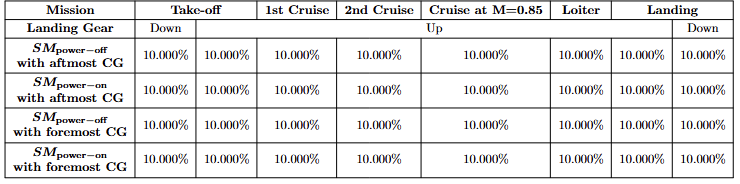 

SM_off_aft * 100

ans =     8.1505    7.8872   14.8849   10.3294   15.6455    9.1480    5.6002    5.8635


SM_on_aft = SM_off_aft  - 0.02;
SM_on_aft * 100

ans =     6.1505    5.8872   12.8849    8.3294   13.6455    7.1480    3.6002    3.8635



SM_off_for * 100

ans =    15.1488   16.5338   23.5315   18.9760   24.2921   17.7946   14.2468   12.8618


SM_on_for = SM_off_for  - 0.02;
SM_on_for * 100

ans =    13.1488   14.5338   21.5315   16.9760   22.2921   15.7946   12.2468   10.8618


## 3. Trim Analysis

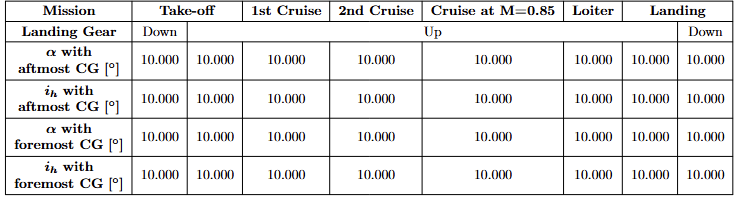

 

 


$$C_L ={\left(C_L \right)}_{w\;} +\eta_h \frac{S_h }{S_w }{\left(C_L \right)}_h$$


**Takeoff**

aftmost (Geardown)

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_TO * (alpha + i_w - a_0_w_TO);

CL_h = d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO));

CD = CD_0_TO + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft_down * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft_down - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft_down - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_aft_down) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_aft_down = double(sol.alpha);

i_h_TO_aft_down = double(sol.i_h);

CD_TO_aft_down = CD_0_TO + ...
K .* ((d_CL_w_TO .* (alpha_TO_aft_down + i_w - a_0_w_TO)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_TO .* ((alpha_TO_aft_down + i_w - a_0_w_TO) .* (1 - d_downwash_TO) + (i_h_TO_aft_down - i_w) - (a_0_h_TO - a_0_w_TO))).^ 2

CD_TO_aft_down = 0.1323

alpha_TO_aft_down = rad2deg(alpha_TO_aft_down)

alpha_TO_aft_down = 7.7795

i_h_TO_aft_down = rad2deg(i_h_TO_aft_down)

i_h_TO_aft_down = -0.5458

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_TO * (alpha + i_w - a_0_w_TO);

CL_h = d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO));

CD = CD_0_TO + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_aft = double(sol.alpha);

i_h_TO_aft = double(sol.i_h);

CD_TO_aft = CD_0_TO + ...
K .* ((d_CL_w_TO .* (alpha_TO_aft + i_w - a_0_w_TO)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_TO .* ((alpha_TO_aft + i_w - a_0_w_TO) .* (1 - d_downwash_TO) + (i_h_TO_aft - i_w) - (a_0_h_TO - a_0_w_TO))).^ 2

CD_TO_aft = 0.1319

alpha_TO_aft = rad2deg(alpha_TO_aft)

alpha_TO_aft = 7.7359

i_h_TO_aft = rad2deg(i_h_TO_aft)

i_h_TO_aft = -0.2325

foremost (Geardown)

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_TO * (alpha + i_w - a_0_w_TO);

CL_h = d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO));

CD = CD_0_TO + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for_down * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for_down - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for_down - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_for_down) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_for_down = double(sol.alpha);

i_h_TO_for_down = double(sol.i_h);

CD_TO_for_down = CD_0_TO + ...
K .* ((d_CL_w_TO .* (alpha_TO_for_down + i_w - a_0_w_TO)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_TO .* ((alpha_TO_for_down + i_w - a_0_w_TO) .* (1 - d_downwash_TO) + (i_h_TO_for_down - i_w) - (a_0_h_TO - a_0_w_TO))).^ 2

CD_TO_for_down = 0.3479

alpha_TO_for_down = rad2deg(alpha_TO_for_down)

alpha_TO_for_down = 21.1279

i_h_TO_for_down = rad2deg(i_h_TO_for_down)

i_h_TO_for_down = -5.7291

foremost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_TO * (alpha + i_w - a_0_w_TO);

CL_h = d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO));

CD = CD_0_TO + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_for = double(sol.alpha);

i_h_TO_for = double(sol.i_h);

CD_TO_for = CD_0_TO + ...
K .* ((d_CL_w_TO .* (alpha_TO_for + i_w - a_0_w_TO)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_TO .* ((alpha_TO_for + i_w - a_0_w_TO) .* (1 - d_downwash_TO) + (i_h_TO_for - i_w) - (a_0_h_TO - a_0_w_TO))).^ 2

CD_TO_for = 0.3232

alpha_TO_for = rad2deg(alpha_TO_for)

alpha_TO_for = 19.9528

i_h_TO_for = rad2deg(i_h_TO_for)

i_h_TO_for = -5.8775

**1st Cruise**

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_c1 * (alpha + i_w - a_0_w_c1);

CL_h = d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1));

CD = CD_0_c1 + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_c1 * (V_c1 ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_c1) / c) + ...
    C_m0_w_c1 + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_c1) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c1_aft = double(sol.alpha);

i_h_c1_aft = double(sol.i_h);

CD_c1_aft = CD_0_c1 + ...
K .* ((d_CL_w_c1 .* (alpha_c1_aft + i_w - a_0_w_c1)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_c1 .* ((alpha_c1_aft + i_w - a_0_w_c1) .* (1 - d_downwash_c1) + (i_h_c1_aft - i_w) - (a_0_h_c1 - a_0_w_c1))).^ 2

CD_c1_aft = 0.0250

alpha_c1_aft = rad2deg(alpha_c1_aft)

alpha_c1_aft = -0.6790

i_h_c1_aft = rad2deg(i_h_c1_aft)

i_h_c1_aft = -1.1459

foremost 

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_c1 * (alpha + i_w - a_0_w_c1);

CL_h = d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1));

CD = CD_0_c1 + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_c1 * (V_c1 ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_c1) / c) + ...
    C_m0_w_c1 + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_c1) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c1_for = double(sol.alpha);

i_h_c1_for = double(sol.i_h);

CD_c1_for = CD_0_c1 + ...
K .* ((d_CL_w_c1 .* (alpha_c1_for + i_w - a_0_w_c1)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_c1 .* ((alpha_c1_for + i_w - a_0_w_c1) .* (1 - d_downwash_c1) + (i_h_c1_for - i_w) - (a_0_h_c1 - a_0_w_c1))).^ 2

CD_c1_for = 0.0356

alpha_c1_for = rad2deg(alpha_c1_for)

alpha_c1_for = 1.9209

i_h_c1_for = rad2deg(i_h_c1_for)

i_h_c1_for = -2.6951

**2nd Cruise**

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_c2 * (alpha + i_w - a_0_w_c2);

CL_h = d_CL_h_c2 * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2));

CD = CD_0_c2 + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_c2 * (V_c2 ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_c2) / c) + ...
    C_m0_w_c2 + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_c2) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c2_aft = double(sol.alpha);

i_h_c2_aft = double(sol.i_h);

CD_c2_aft = CD_0_c2 + ...
K .* ((d_CL_w_c2 .* (alpha_c2_aft + i_w - a_0_w_c2)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_c2 .* ((alpha_c2_aft + i_w - a_0_w_c2) .* (1 - d_downwash_c2) + (i_h_c2_aft - i_w) - (a_0_h_c2 - a_0_w_c2))).^ 2

CD_c2_aft = 0.0251

alpha_c2_aft = rad2deg(alpha_c2_aft)

alpha_c2_aft = -0.3724

i_h_c2_aft = rad2deg(i_h_c2_aft)

i_h_c2_aft = -0.8881

foremost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_c2 * (alpha + i_w - a_0_w_c2);

CL_h = d_CL_h_c2 * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2));

CD = CD_0_c2 + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_c2 * (V_c2 ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_c2) / c) + ...
    C_m0_w_c2 + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_c2) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c2_for = double(sol.alpha);

i_h_c2_for = double(sol.i_h);

CD_c2_for = CD_0_c2 + ...
K .* ((d_CL_w_c2 .* (alpha_c2_for + i_w - a_0_w_c2)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_c2 .* ((alpha_c2_for + i_w - a_0_w_c2) .* (1 - d_downwash_c2) + (i_h_c2_for - i_w) - (a_0_h_c2 - a_0_w_c2))).^ 2

CD_c2_for = 0.0367

alpha_c2_for = rad2deg(alpha_c2_for)

alpha_c2_for = 2.4941

i_h_c2_for = rad2deg(i_h_c2_for)

i_h_c2_for = -2.3534

**Cruise at M=0.85**

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_cmax * (alpha + i_w - a_0_w_cmax);

CL_h = d_CL_h_cmax * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax));

CD = CD_0_cmax + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_cmax * (V_cmax ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_cmax) / c) + ...
    C_m0_w_cmax + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_cmax) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_cmax_aft = double(sol.alpha);

i_h_cmax_aft = double(sol.i_h);

CD_cmax_aft = CD_0_cmax + ...
K .* ((d_CL_w_cmax .* (alpha_cmax_aft + i_w - a_0_w_cmax)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_cmax .* ((alpha_cmax_aft + i_w - a_0_w_cmax) .* (1 - d_downwash_cmax) + (i_h_cmax_aft - i_w) - (a_0_h_cmax - a_0_w_cmax))).^ 2

CD_cmax_aft = 0.0246

alpha_cmax_aft = rad2deg(alpha_cmax_aft)

alpha_cmax_aft = -0.8116

i_h_cmax_aft = rad2deg(i_h_cmax_aft)

i_h_cmax_aft = -1.1686

foremost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_cmax * (alpha + i_w - a_0_w_cmax);

CL_h = d_CL_h_cmax * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax));

CD = CD_0_cmax + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_cmax * (V_cmax ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_cmax) / c) + ...
    C_m0_w_cmax + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_cmax) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_cmax_for = double(sol.alpha);

i_h_cmax_for = double(sol.i_h);

CD_cmax_for = CD_0_cmax + ...
K .* ((d_CL_w_cmax .* (alpha_cmax_for + i_w - a_0_w_cmax)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_cmax .* ((alpha_cmax_for + i_w - a_0_w_cmax) .* (1 - d_downwash_cmax) + (i_h_cmax_for - i_w) - (a_0_h_cmax - a_0_w_cmax))).^ 2

CD_cmax_for = 0.0344

alpha_cmax_for = rad2deg(alpha_cmax_for)

alpha_cmax_for = 1.6727

i_h_cmax_for = rad2deg(i_h_cmax_for)

i_h_cmax_for = -2.6853

**Loiter**

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_loi * (alpha + i_w - a_0_w_loi);

CL_h = d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi));

CD = CD_0_loi + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_loi * (V_loi ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_loi) / c) + ...
    C_m0_w_loi + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_loi) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_loi_aft = double(sol.alpha);

i_h_loi_aft = double(sol.i_h);

CD_loi_aft = CD_0_loi + ...
K .* ((d_CL_w_loi .* (alpha_loi_aft + i_w - a_0_w_loi)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_loi .* ((alpha_loi_aft + i_w - a_0_w_loi) .* (1 - d_downwash_loi) + (i_h_loi_aft - i_w) - (a_0_h_loi - a_0_w_loi))).^ 2

CD_loi_aft = 0.0317

alpha_loi_aft = rad2deg(alpha_loi_aft)

alpha_loi_aft = 1.9226

i_h_loi_aft = rad2deg(i_h_loi_aft)

i_h_loi_aft = -1.2075

foremost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_loi * (alpha + i_w - a_0_w_loi);

CL_h = d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi));

CD = CD_0_loi + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_loi * (V_loi ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_loi) / c) + ...
    C_m0_w_loi + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_loi) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_loi_for = double(sol.alpha);

i_h_loi_for = double(sol.i_h);

CD_loi_for = CD_0_loi + ...
K .* ((d_CL_w_loi .* (alpha_loi_for + i_w - a_0_w_loi)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_loi .* ((alpha_loi_for + i_w - a_0_w_loi) .* (1 - d_downwash_loi) + (i_h_loi_for - i_w) - (a_0_h_loi - a_0_w_loi))).^ 2

CD_loi_for = 0.0601

alpha_loi_for = rad2deg(alpha_loi_for)

alpha_loi_for = 6.7701

i_h_loi_for = rad2deg(i_h_loi_for)

i_h_loi_for = -3.5575

**Landing**

aftmost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_L * (alpha + i_w - a_0_w_L);

CL_h = d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L));

CD = CD_0_L + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_aft) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_L_aft = double(sol.alpha);

i_h_L_aft = double(sol.i_h);

CD_L_aft = CD_0_L + ...
K .* ((d_CL_w_L .* (alpha_L_aft + i_w - a_0_w_L)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_L .* ((alpha_L_aft + i_w - a_0_w_L) .* (1 - d_downwash_L) + (i_h_L_aft - i_w) - (a_0_h_L - a_0_w_L))).^ 2

CD_L_aft = 0.1545

alpha_L_aft = rad2deg(alpha_L_aft)

alpha_L_aft = 4.1963

i_h_L_aft = rad2deg(i_h_L_aft)

i_h_L_aft = 0.7462

aftmost (Geardown)

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_L * (alpha + i_w - a_0_w_L);

CL_h = d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L));

CD = CD_0_L + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_aft_down * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_aft_down - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_aft_down - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_aft_down) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_L_aft_down = double(sol.alpha);

i_h_L_aft_down = double(sol.i_h);

CD_L_aft_down = CD_0_L + ...
K .* ((d_CL_w_L .* (alpha_L_aft_down + i_w - a_0_w_L)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_L .* ((alpha_L_aft_down + i_w - a_0_w_L) .* (1 - d_downwash_L) + (i_h_L_aft_down - i_w) - (a_0_h_L - a_0_w_L))).^ 2

CD_L_aft_down = 0.1549

alpha_L_aft_down = rad2deg(alpha_L_aft_down)

alpha_L_aft_down = 4.2387

i_h_L_aft_down = rad2deg(i_h_L_aft_down)

i_h_L_aft_down = 0.4059

foremost

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_L * (alpha + i_w - a_0_w_L);

CL_h = d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L));

CD = CD_0_L + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_for) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_L_for = double(sol.alpha);

i_h_L_for = double(sol.i_h);

CD_L_for = CD_0_L + ...
K .* ((d_CL_w_L .* (alpha_L_for + i_w - a_0_w_L)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_L .* ((alpha_L_for + i_w - a_0_w_L) .* (1 - d_downwash_L) + (i_h_L_for - i_w) - (a_0_h_L - a_0_w_L))).^ 2

CD_L_for = 0.2951

alpha_L_for = rad2deg(alpha_L_for)

alpha_L_for = 13.4406

i_h_L_for = rad2deg(i_h_L_for)

i_h_L_for = -3.5956

foremost (Geardown)

syms alpha i_h

assume(alpha < 0.5)
assume(alpha > -0.5)
assume(i_h < 0.5)
assume(i_h > -0.5)

% Define the equations

CL_w = d_CL_w_L * (alpha + i_w - a_0_w_L);

CL_h = d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L));

CD = CD_0_L + K * (CL_w ^ 2) + n_h * (S_h / S_w) * K_tail * CL_h ^ 2;

eqCL = ...
    CL_w + ...
    n_h * (S_h / S_w) * CL_h - ...
    (W_CG_for_down * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    CL_w * ((x_CG_for_down - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * CL_h  * (S_h / S_w) * ((x_CG_for_down - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_for_down) * CD / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for alpha and i_h
alpha_L_for_down = double(sol.alpha);

i_h_L_for_down = double(sol.i_h);

CD_L_for_down = CD_0_L + ...
K .* ((d_CL_w_L .* (alpha_L_for_down + i_w - a_0_w_L)) .^ 2) + ...
n_h .* (S_h / S_w) .* K_tail .* (d_CL_h_L .* ((alpha_L_for_down + i_w - a_0_w_L) .* (1 - d_downwash_L) + (i_h_L_for_down - i_w) - (a_0_h_L - a_0_w_L))).^ 2

CD_L_for_down = 0.3132

alpha_L_for_down = rad2deg(alpha_L_for_down)

alpha_L_for_down = 14.3322

i_h_L_for_down = rad2deg(i_h_L_for_down)

i_h_L_for_down = -3.4440